%{
Newtons method takes an initial guess and predicts the roots. The
derivative cannot equal zero at any point
%}


F = @(x) atan(x) - 1;
FPRIME = @(x) (1)/(x^2+1);
INITIAL_GUESS = 2;
INITIAL_GUESS2 = -2;
ERROR_TOLERANCE = 10^-8;
MAX_ITER = 100;

[c,n,err] = newtons_method(F,FPRIME,INITIAL_GUESS,ERROR_TOLERANCE,MAX_ITER)

c = 1.5574

n = 4

err = 2.1656e-11

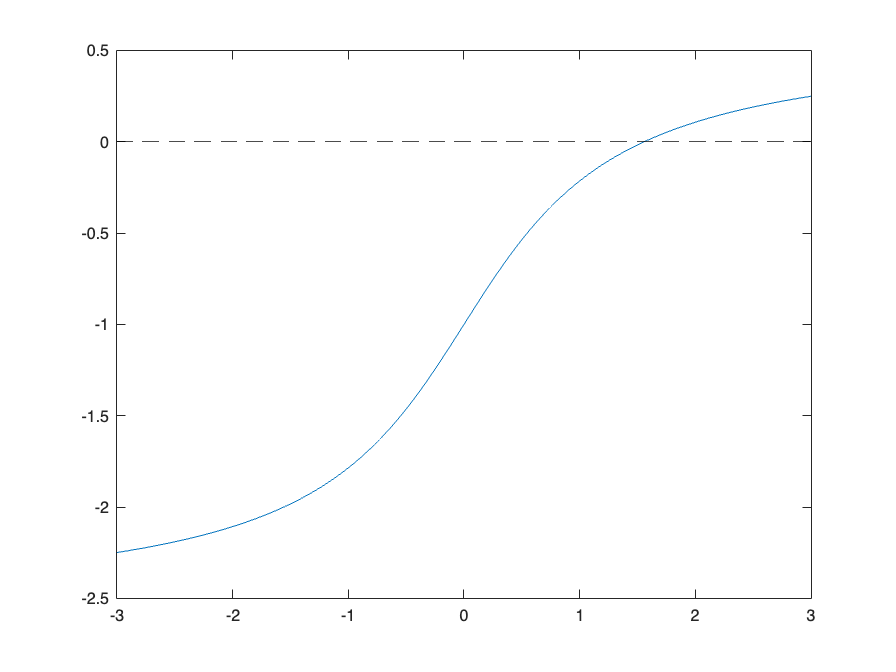


function [c,n,err] = newtons_method(F,FPRIME,INITIAL_GUESS,ERROR_TOLERANCE,MAX_ITER)    
    x = INITIAL_GUESS;

    n = 0;

    while n < MAX_ITER 
        if FPRIME(x) == 0
        error("Derivative equals zero");
        end
        c = x - F(x)/FPRIME(x);
        err = abs(c - x);
        if err < ERROR_TOLERANCE
            return
        end
        n = n + 1;
        x = c;

    end

end
%took 4 iterations to converge wtih initial guess == 2
%with initial guess == -2 it doesnt converge because the derivative becomes 0


%plotting
x = -3:.001:3;
y = F(x);
plot(x,y)
hold on;
yline(0, '--k');